# Explore Graph Database Structure

This example shows how to traverse a graph and explore its structure using the MATLAB® interface to Neo4j®. For details about the MATLAB interface to Neo4j, see [Working with MATLAB Interface to Neo4j](docid:database_ug.bveys16-1).

Assume that you have graph data stored in a Neo4j database that represents a social neighborhood. This database has seven nodes and eight relationships. Each node has only one unique property key `name` with a value ranging from `User1` through `User7`. Each relationship has the type `knows`.

The local machine hosts the Neo4j database with the port number `7474`, user name `neo4j`, and password `matlab`. This figure provides a visual representation of the data in the database.

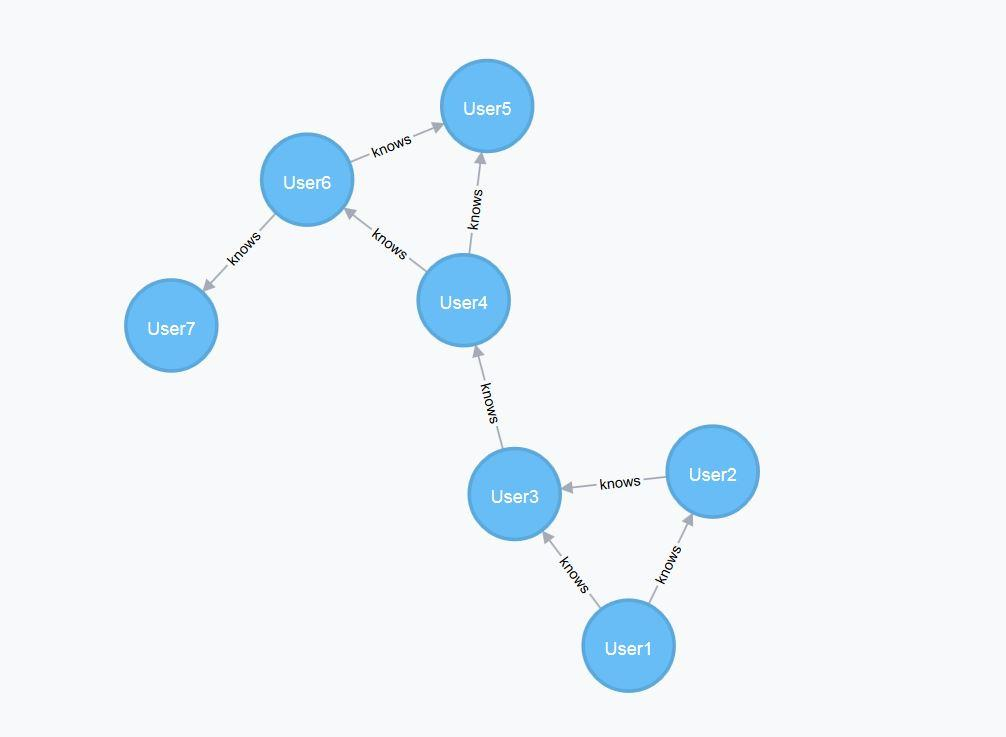

## Connect to Neo4j Database

Create a Neo4j connection object `neo4jconn` using the URL `http://localhost:7474/db/data`, user name `neo4j`, and password `matlab`.

url = 'http://localhost:7474/db/data';
username = 'neo4j';
password = 'matlab';

neo4jconn = neo4j(url,username,password);

Check the `Message` property of the Neo4j connection object `neo4jconn`. The blank `Message` property indicates a successful connection.

neo4jconn.Message

## Explore Structure of Entire Graph

Find all the node labels in the Neo4j database using the Neo4j connection object `neo4jconn`.

nlabels = nodeLabels(neo4jconn)

Find all the relationship types in the Neo4j database.

reltypes = relationTypes(neo4jconn)

Find the property keys in the Neo4j database.

propkeys = propertyKeys(neo4jconn)

## Search for Nodes

Search for all the nodes with the node label `Person`. The `nodesinfo` output argument contains node labels, node data, and the `Neo4jNode` objects for each matched node.

nlabel = 'Person';

nodesinfo = searchNode(neo4jconn,nlabel)

Search for the node with the node identifier `2`. The `nodeinfo` output argument contains the node identifier, node data, and node labels for the node with node identifier `2`.

nodeid = 2;

nodeinfo = searchNodeByID(neo4jconn,nodeid)

## Search for Relationships

Search for incoming relationship types that belong to the node `nodeinfo`.

nodereltypes = nodeRelationTypes(nodeinfo,'in')

Search for the degree of all incoming relationships that belong to the node `nodeinfo`.

degree = nodeDegree(nodeinfo,'in')

Search for the relationship with the node identifier `4`.

relationid = 4;

relationinfo = searchRelationByID(neo4jconn,relationid)

Search for all incoming relationships that belong to the node `nodeinfo`. The `relinfo` output argument contains data about the start and end nodes and all matched relationships from the origin node.

relinfo = searchRelation(neo4jconn,nodeinfo,'in')

## Retrieve Entire Graph

Retrieve the entire graph using node labels `nlabels`.

graphinfo = searchGraph(neo4jconn,nlabels)

`graphinfo` contains node data for all start and end nodes for each matched relationship. `graphinfo` also contains relationship data for each matched relationship.

## Close Database Connection

close(neo4jconn)

*Copyright 2018 The MathWorks, Inc.*